# Laboratorio di Automatica (Prova del 23 Giugno 2020)

Riccardo Antonello ([antonello@dei.unipd.it](mail:antonello@dei.unipd.it)) and Luca Schenato ([schenato@dei.unipd.it](mail:schenato@dei.unipd.it)) 

June 23, 2020

Dept. of Information Engineering, University of Padova

## Esercizio 1

Si consideri il sistema di controllo di posizione per un motore elettrico in corrente continua illustrato in Fig. 1, dove:


$$P(s) = \frac{Y(s)}{U(s)} = \frac{k_m}{s(T_m\,s + 1)} \quad \text{con} \quad k_m = 5.2\,,\quad T_m = 0.03$$
  

è la funzione di trasferimento del motore, da ingresso in tensione $u\,\mathrm{[V]}$ ad uscita in posizione $y\,\mathrm{[rad]}$, mentre


$$C(s) = \frac{U_C(s)}{E(s)} = k \left( \frac{\tau\,s + 1}{s}\right)
\quad \text{con} \quad k\geq 0\,,
\quad \tau = 0.42$$


è la funzione di trasferimento del controllore di posizione, con ingresso l'errore di posizione $e\,\mathrm{[rad]}$ ed uscita la tensione di comando $u\,[\mathrm{V}]$.

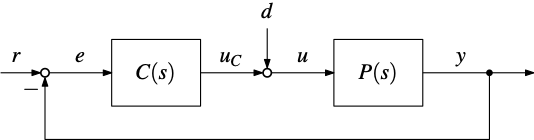

**Figura 1**: Sistema di controllo di posizione.

Utilizzando *soltanto* le routines del Control System Toolbox (CST), si svolgano i seguenti punti:

1)  Assumendo inizialmente $k=1$, mostrare il diagramma di Bode della funzione di trasferimento d'anello $L(s)=P(s)C(s)$, e calcolare quindi  pulsazione di attraversamento $\omega_{gc}$ e margine di fase $\varphi_m$ del sistema.   

*Soluzione*.

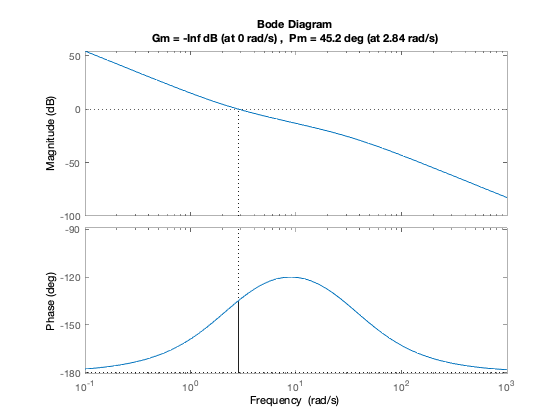

%    plant tf
km = 5.2;
Tm = 0.03;
sysP = tf(km, [Tm, 1, 0]);

%   controller tf
k = 1;
tau = 0.42;
sysC = k * tf([tau, 1], [1, 0]);

%   loop tf
sysL = sysP*sysC;

%   phase margin & gain crossover freq
figure;
margin(sysL);

2)  Sempre assumendo $k = 1$, valutare la risposta$y$ del sistema in catena chiusa ad un segnale di riferimento $r$ a gradino unitario, applicato all'istante $t=0$. Determinare successivamente sovraelongazione percentuale e tempo di assestamento al $5\%$ della risposta al gradino.

*Soluzione*.

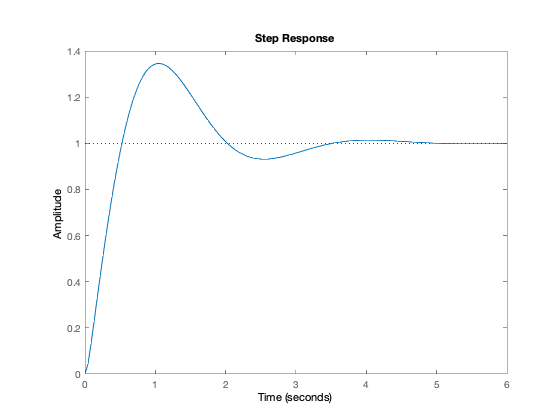

%   closed-loop tf
sysT = feedback(sysL,1);

%   unit step response
figure;
step(sysT);


%   step response info
info = stepinfo(sysT, 'SettlingTimeThreshold', 0.05);
fprintf('Overshoot: %2.4f %%\n', info.Overshoot);

Overshoot: 34.5867 %


fprintf('Settling time: %2.4f s\n', info.SettlingTime);

Settling time: 2.9108 s


3) Determinare il valore di guadagno $k^*$ del controllore che massimizza il margine di fase del sistema. Specificare inoltre pulsazione di attraversamento $\omega_{gc}^*
$ e margine di fase $\varphi_m^*$ ottenuti in corrispondenza a tale valore di guadagno.

*Soluzione*.

%   max search (numerical)
w = logspace(-1, 3, 500);
[magL, phaL] = bode(sysL, w);

magL = squeeze(magL);
phaL = squeeze(phaL);
[phaL_max, i_max] = max(phaL);

%   max phase margin phim* 
phim_max = phaL_max + 180;

%   controller gain k*
k_opt = 1/magL(i_max);

%   gain crossover freq wgc*
wgc_opt = w(i_max);

fprintf('Controller gain: %2.4f\n', k_opt);

Controller gain: 4.0587


fprintf('Phase margin: %2.4f deg\n', phim_max);

Phase margin: 60.0733 deg


fprintf('Gain crossover freq: %2.4f rad/s\n', wgc_opt);

Gain crossover freq: 8.8694 rad/s


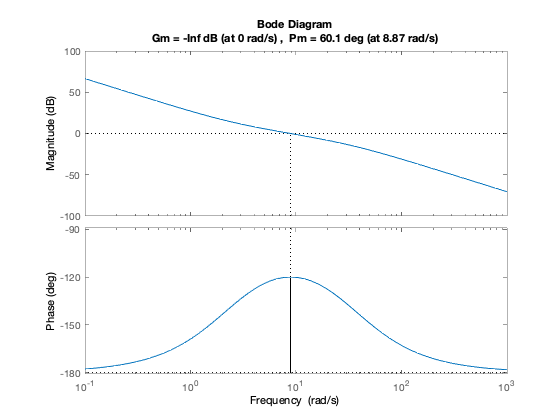


%   controller tf with gain k*
sysC_opt = k_opt * tf([tau, 1], [1, 0]);

%   loop tf with gain k*
sysL_opt = sysP*sysC_opt;

%   phase margin & gain crossover freq
figure;
margin(sysL_opt);

4) Ripetere il punto 2 con il valore di guadagno $k^*$ ottenuto al punto precedente.

*Soluzione*.

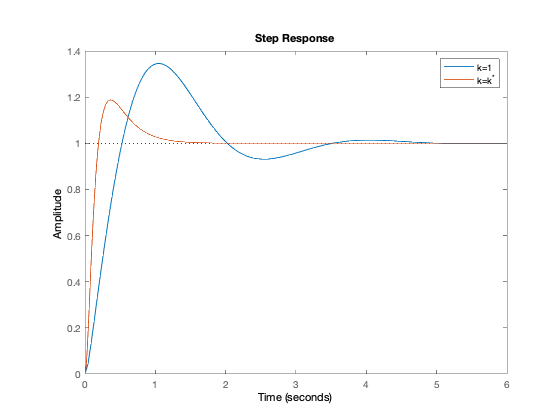

%   closed-loop tf
sysT_opt = feedback(sysL_opt,1);

%   unit step response
figure;
step(sysT, sysT_opt);
legend('k=1', 'k=k^*');


%   step response info
info = stepinfo(sysT_opt, 'SettlingTimeThreshold', 0.05);
fprintf('Overshoot: %2.4f %%\n', info.Overshoot);

Overshoot: 18.7652 %


fprintf('Settling time: %2.4f s\n', info.SettlingTime);

Settling time: 0.8462 s
